PAZ_st.name='PAZ'; 
PAZ_st.lat=33.50;
PAZ_st.lon=-112.10;
PAZ_st.alt=372;

PAZ_rd=read_betsy('phoenix_head',PAZ_st.name);

datevec(PAZ_rd.Time(1))

ans =         1997           4           2           0           0           0

datevec(PAZ_rd.Time(end))

ans =         2018           7           1           0           0           0

prctile(PAZ_rd.U_S,[5, 50, 95])

ans =    13.6100   31.8725   67.9580

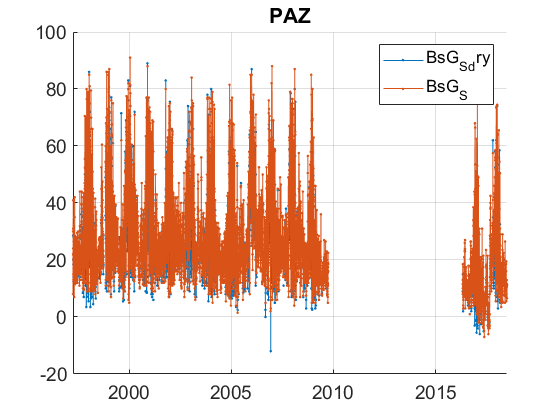

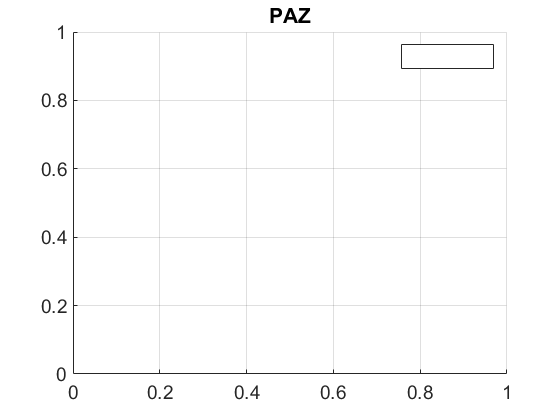

plotFigControl(PAZ_rd,PAZ_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives

% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE3=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% PAZ_cal=compute_exp_SSA(PAZ_rd,lambdaSC, lambdaAE3);
% plotFigControl_cal(PAZ_cal, PAZ_st.name);

%Questions:
%problems:
% hole from end 2009 to April 2016

PAZ_t=timetable(PAZ_rd.Time);
% begin at the beginning of a year:1998
%end year: 2017


